maxTime = 6500;
volumes = 200;
% lambda = 0.1
lambda = [1:200]./10000;
% lambda = [ones(1, volumes/2), 2*ones(1, volumes/2)];

solver = DiffusionSolver( ...
    volumes, ...
    maxTime, ...
    lambda);

% solver.setStartingCondition( @(x) abs(sin(5*x)) );
solver.setStartingCondition();
% solver.setStartingCondition(@(x) 0);
% solver.setDirichletBC(round(volumes/3), 5);
% solver.setDirichletBC(volumes, 5);
% solver.setDirichletBC(2, 5);
% solver.setSinglePointNeumannBC(68, 20, 1, 600);


solver.solve()


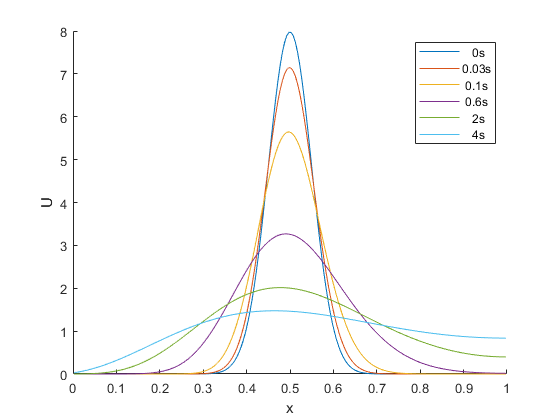


% frame = 1
clf
hold on
ylabel('U')
xlabel('x')
solver.plot(1)
solver.plot(50)
solver.plot(200)
solver.plot(1000)
solver.plot(3000)
solver.plot(6000)
legend(strcat(...
    num2str(...
    [solver.currentTime(1);...
    solver.currentTime(50); ...
    solver.currentTime(200); ...
    solver.currentTime(1000); ...
    solver.currentTime(3000);  ...
    solver.currentTime(6000)], 1)...
    , 's'))
hold off

% hold on
% solver(1).plotAnimated(100)
% solver(2).plotAnimated(100)
% solver(3).plotAnimated(100)
% hold off

solver.plotAnimated(25)
solver.plotIntegral()

% for timestep = 1:50:2000
%     plot(solver(1).xVector, solver(1).U(:, timestep), 'g-*', solver(2).xVector, solver(2).U(:, timestep), 'r--o', solver(3).xVector, solver(3).U(:, timestep), 'b')
%     ylim([0 8])
%     title(solver(1).currentTime(timestep), timestep)
%     drawnow;
%     
% %     plot(solver(2).xVector, solver(2).U(:, timestep), 'r--o')
% %     ylim([0 8])
% %     title(solver(1).currentTime(timestep), timestep)
% %     drawnow;
% %     
% %     plot(solver(3).xVector, solver(3).U(:, timestep), 'b')
% %     ylim([0 8])
% %     title(solver(1).currentTime(timestep), timestep)
% %     drawnow;
% end